# System Identification of a robot arm

Ejecutar modelo `cst_robotarm_identi.slx`. Genera las siguientes salids en el ws:

- Ts_identi (fixed). 

- position (en radianes)

- time (segundos)

Ts_identi = 1e-3;  % Tiempo de muestreo (segundos)

## Motor 1

joint1_only = 60;
joint2_only = 0;
joint3_only = 0;
joint4_only = 0;
joint5_only = 0;
joint6_only = 0;

% Puntos para identificación
t1 = 2  % Primer punto para identificación

t1 = 2

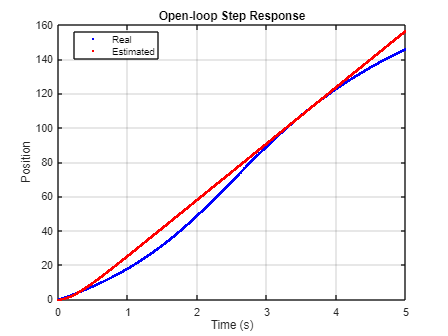

G =
 
       32.8
  --------------
  0.2307 s^2 + s
 
Continuous-time transfer function.
Model Properties
Estimated transfer function:
Estimation error: 591.36%

G =
 
       32.8
  --------------
  0.2307 s^2 + s
 
Continuous-time transfer function.


t2 = 4.9;  % Segundo punto para identificación

% Identificar el sistema
G = identify_position_TF(Ts_identi, position(:,1)*180/pi, time.Data, t1, t2)

## Motor 2

joint1_only = 0;
joint2_only = 150;
joint3_only = 0;
joint4_only = 0;
joint5_only = 0;
joint6_only = 0;

% Puntos para identificación
t1 = 2  % Primer punto para identificación

t1 = 2

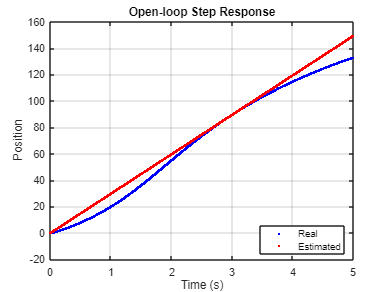

G =
 
       29.85
  ----------------
  0.001451 s^2 + s
 
Continuous-time transfer function.
Model Properties
Estimated transfer function:
Estimation error: 706.38%

G =
 
       29.85
  ----------------
  0.001451 s^2 + s
 
Continuous-time transfer function.


t2 = 4.9;  % Segundo punto para identificación

% Identificar el sistema
G = identify_position_TF(Ts_identi, position(:,2)*180/pi-90, time.Data, t1, t2)



% G =
% 
%        32.8
%   --------------
%   0.2307 s^2 + s
% 
% Continuous-time transfer function.
% Model Properties
% Estimated transfer function:
% Estimation error: 591.36%


## Motor 3

joint1_only = 60;
joint2_only = 150;
joint3_only = 70;
joint4_only = 0;
joint5_only = 0;
joint6_only = 0;

% Puntos para identificación
t1 = 2  % Primer punto para identificación
t2 = 4;  % Segundo punto para identificación

% Identificar el sistema
G = identify_position_TF(Ts_identi, position(:,2)*180/pi-90, time.Data, t1, t2)


% G =
% 
%        29.85
%   ----------------
%   0.001451 s^2 + s
% 
% Continuous-time transfer function.
% Model Properties
% Estimated transfer function:
% Estimation error: 706.38%
